# NN decoder for the micro-scale MC link

**Description: **This code implements a decoder of binary transmissions in molecular communication (MC) channels with the testbed in Fig. 1. The tesbed is fully described in [[1]](http://dx.doi.org/10.1109/BalkanCom55633.2022.9900720) and the dataset is accesible in [[2]](https://ieee-dataport.org/documents/dataset-macroscale-molecular-communication-testbed). As for the decoder this code implements a bidirectional long short-term memory (BiLSTM) architecture following the work in [3].

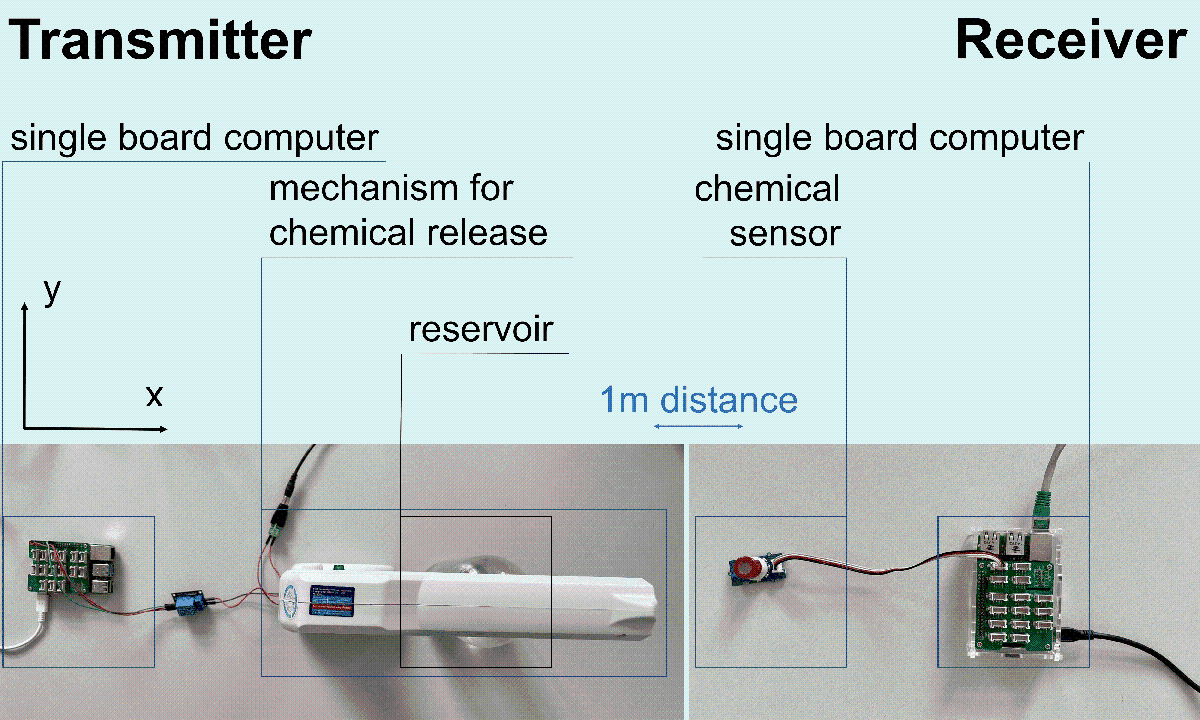

Fig. 1: Experimental Testbed used for MC as developed in [[1]](http://dx.doi.org/10.1109/BalkanCom55633.2022.9900720).

clc;
clear all;
close all;


### Loading the parameters

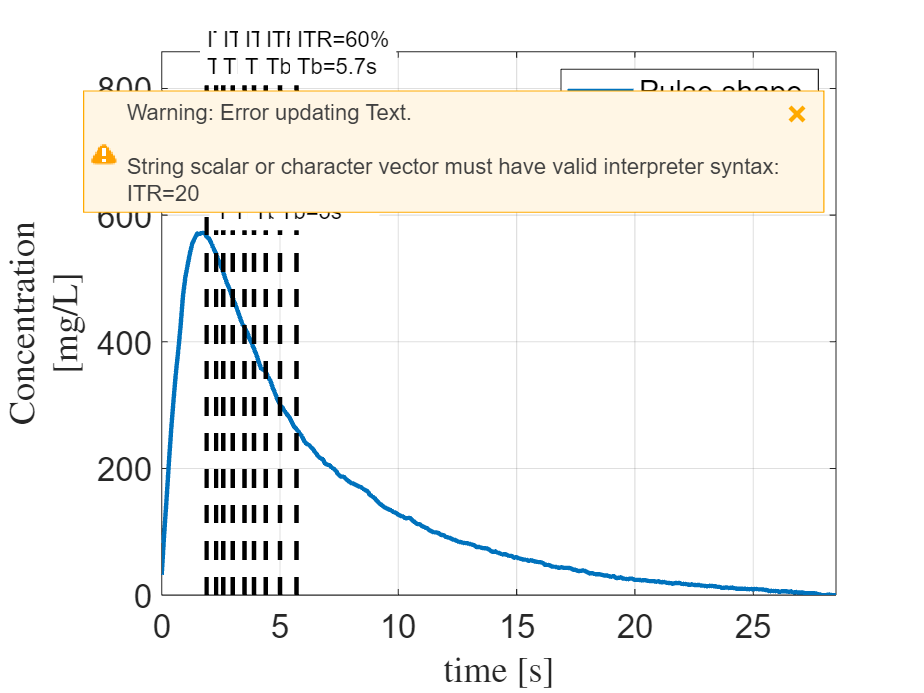

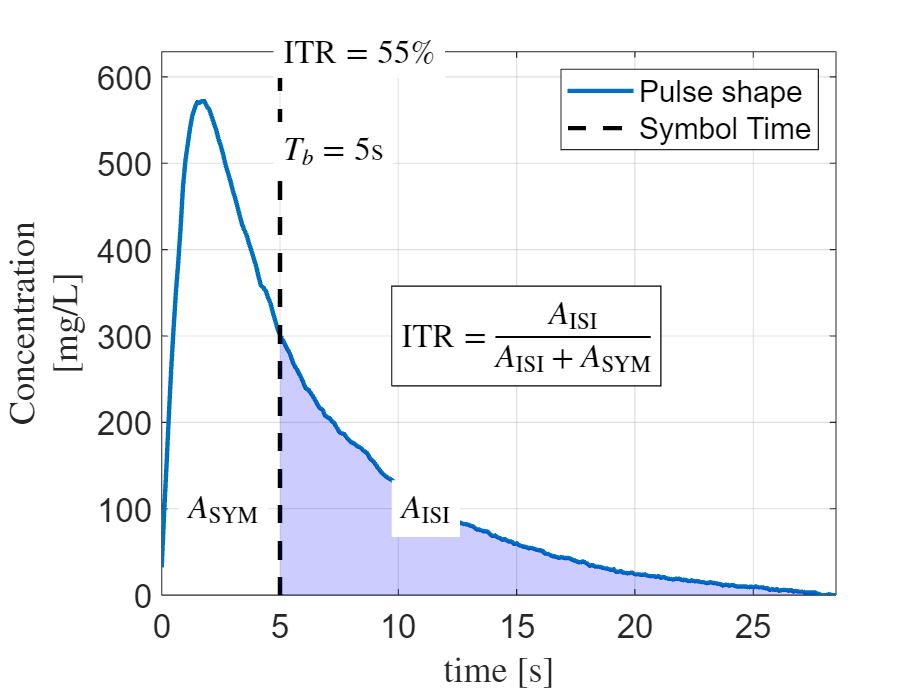

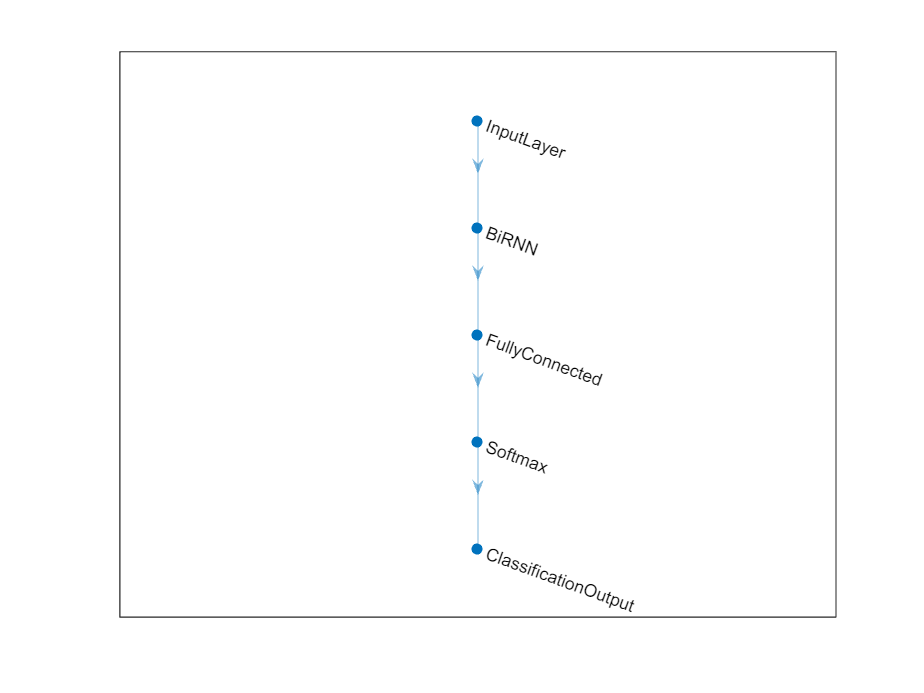

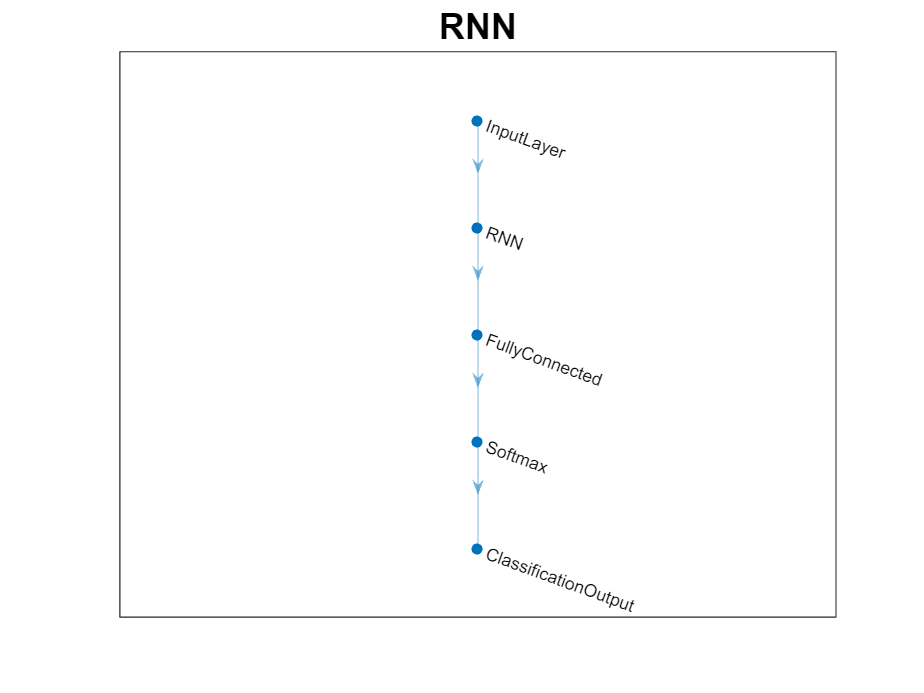

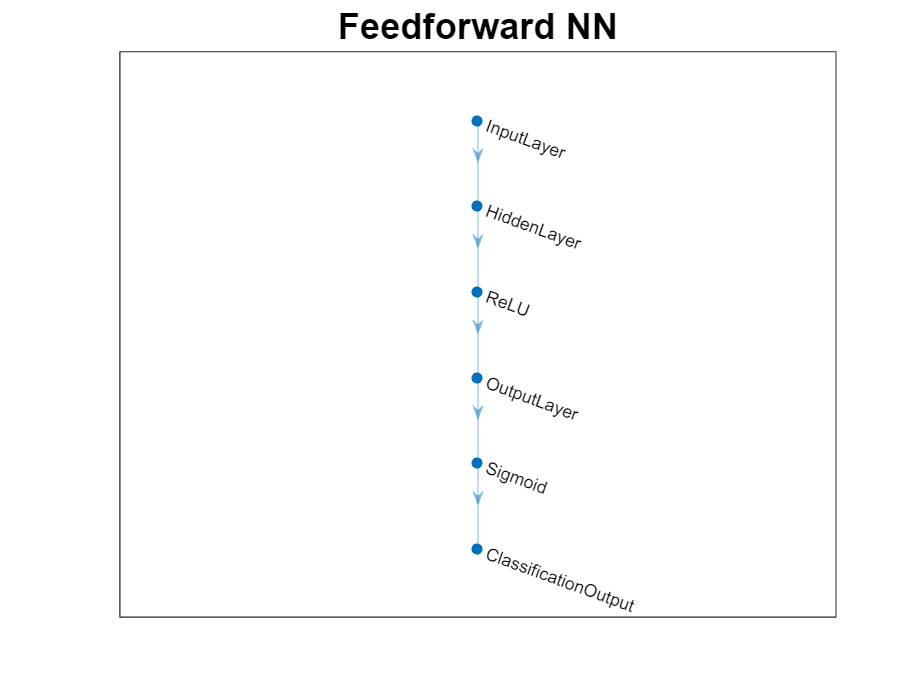

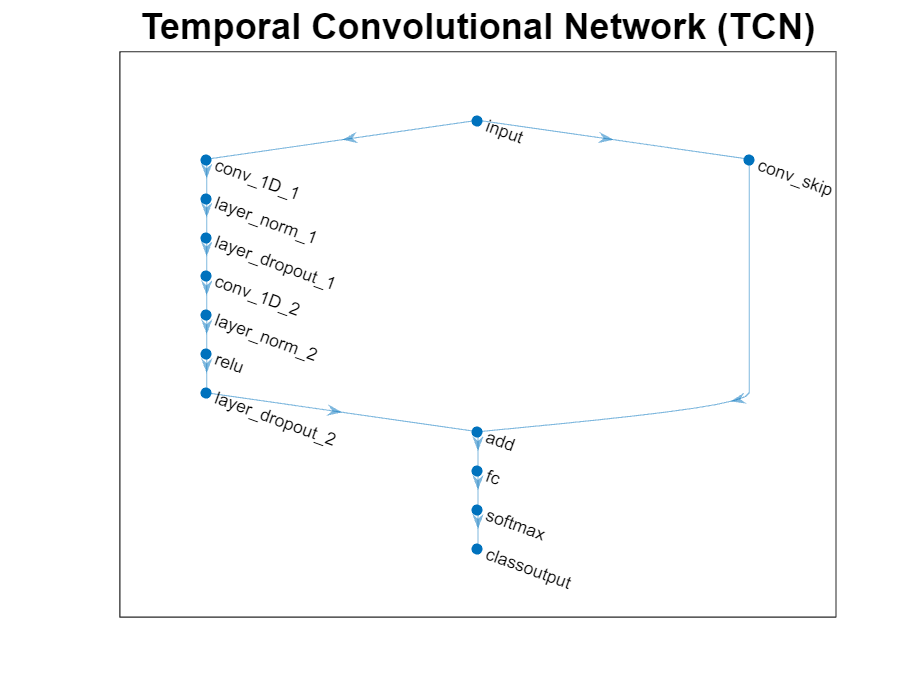

Parameters

### Plotting

**Description**: We plot in this block the results of the trainned NNs in the subsequent blocks.

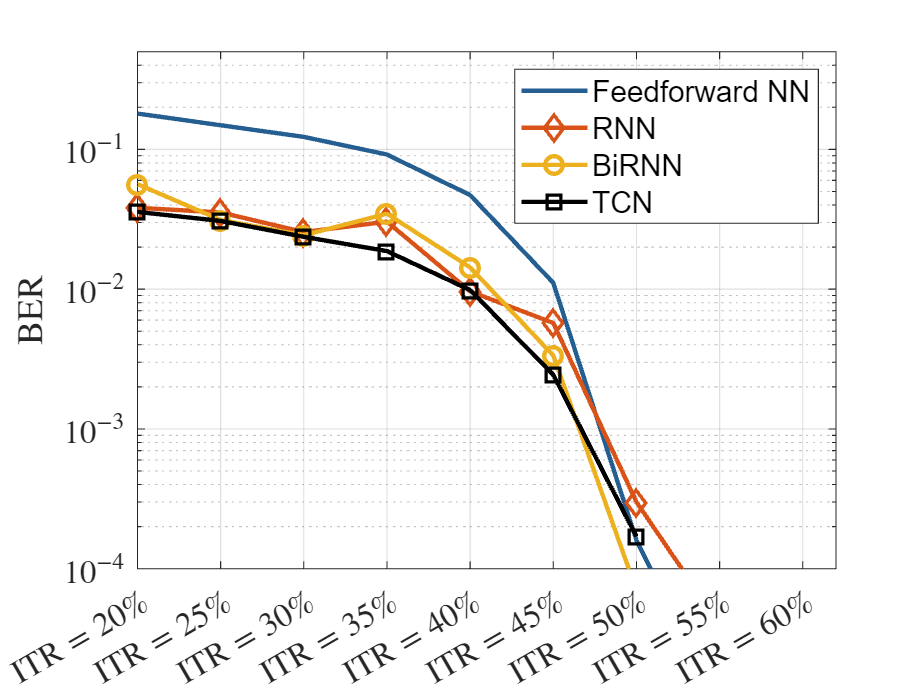

load NN/BER_NN.mat

figure;% open a new plot canvas
color = {'#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#4DBEEE','#A2142F'}; %list of colors from https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html
line_width=linspace(1,3,length(color));%specify the width for each line in the plot
marker={'-','-+','-d','-.','-x','-o','-s','-*','-|','-^'};% marker symbols are given at https://www.mathworks.com/help/matlab/creating_plots/create-line-plot-with-markers.html

%feedforward NN
semilogy(ITR_vector,BER_net_ffNN,'Color','#255E91','LineWidth',2); grid on;hold on
%BiRNN
semilogy(ITR_vector,BER_net_RNN,marker{3},'Color','#D95319','LineWidth',2,'MarkerSize',8);
%RNN
semilogy(ITR_vector,BER_net_BiRNN,marker{6},'Color','#EDB120','LineWidth',2,'MarkerSize',8);
%TCN
semilogy(ITR_vector,BER_net_TCN,marker{7},'Color','black','LineWidth',2,'MarkerSize',8);
%xlabel
set(gca, 'XTick', ITR_vector);
x_ticks=cell(1,length(ITR_vector));
for m=1:length(ITR_vector)
  x_ticks{m}=strcat("$\mathrm{ITR}=",num2str(ITR_vector(m)),"\%$");
end
set(gca, 'XTickLabel', x_ticks, 'TickLabelInterpreter', 'latex');

%%uncomment below to plot T_b instead
% x_tick_number(1:2:2*length(ITR_vector))=ITR_vector;
% x_tick_number(2:2:2*length(ITR_vector))=ITR_vector+2;
% set(gca, 'XTick', x_tick_number);
% x_ticks=cell(1,2*length(ITR_vector));
% k=1;
% z=1;
% for m=1:2*length(ITR_vector)
%     if(mod(m,2))        
%         x_ticks{m}=strcat("$T_b=",num2str(T_b_vector(k)),"s$");
%         k=k+1;
%     else
%         x_ticks{m}=strcat("$\mathrm{ITR}=",num2str(ITR_vector(z)),"\%$");
%         z=z+1;
%     end
% end
% set(gca, 'XTickLabel', x_ticks, 'TickLabelInterpreter', 'latex');

%ylabel
ylabel('BER','Interpreter','latex');
legend('Feedforward NN','RNN','BiRNN','TCN');
set(gca,'FontSize',fontsize);
axis([ITR_vector(1) ITR_vector(end)+2 1e-4 0.5]);

### Conforming the database

**Description**: This block creates the dataset of training and testing arrays for each different ITR parameter selection. The ITR selection is specified as a vector in the `Parameters.mlx` file.

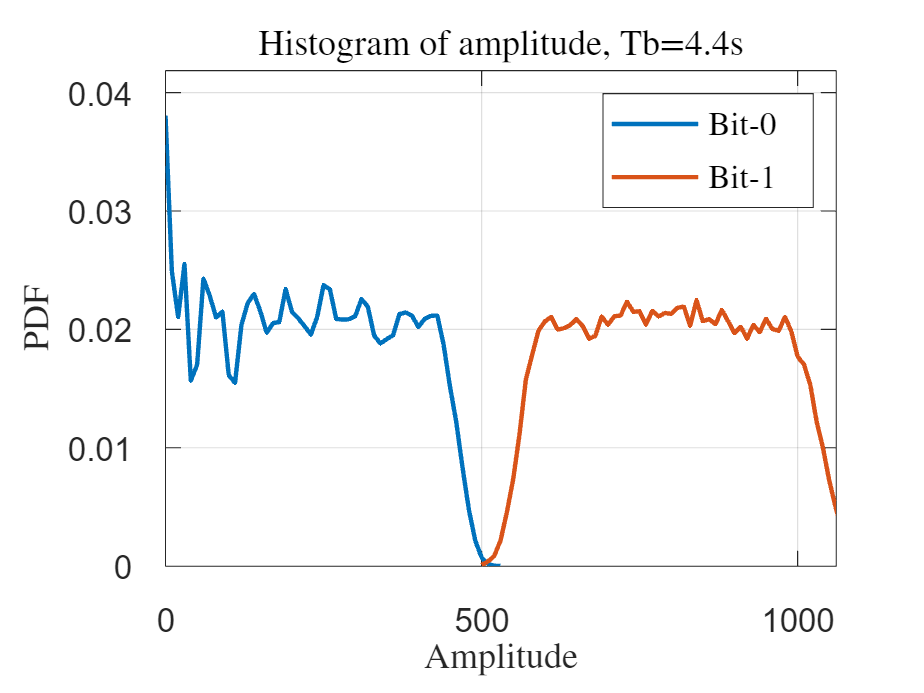

% %uncomment the lines below if dataset-related parameters are modified in
% %the Parameters.mlx file
for k=1:length(T_b_vector)
    %specify the correspoding symbol time according to the calculations
    %made in the Paremeters.mlx file
    T_b=T_b_vector(k);
    Dataset_compiler;
    %storing the sequence
    str=strcat('Datasets/Dataset_ITR_',num2str(ITR_vector(k)),'_T_b_',num2str(T_b),'s.mat');
    save(str,"XTrain","YTrain","XTest","YTest","T_b","ITR_vector","T_b_vector");
end

### Training the models

#### Train the bidirectional LSTM Network

Train the bidirectional LSTM network with the specified training options by using `trainNetwork`.

tic
for k=1:length(ITR_vector)
    disp(strcat(num2str(k/length(ITR_vector)*100),"%"))%progress indicator
    %loading the database
    str=strcat('Datasets/Dataset_ITR_',num2str(ITR_vector(k)),'_T_b_',num2str(T_b_vector(k)),'s.mat');
    load(str);
    [net_BiRNN, traininfo_BiRNN] = trainNetwork(XTrain,YTrain,layers_BiRNN,options);
    str=strcat('NN/net_BiRNN_',num2str(ITR_vector(k)),'_T_b_',num2str(T_b),'s.mat');
    save(str,"net_BiRNN","traininfo_BiRNN");
end

11.1111%


toc

### Train the RNN LSTM Network

Train the recurrent LSTM network with the specified training options by using `trainNetwork`.

100%


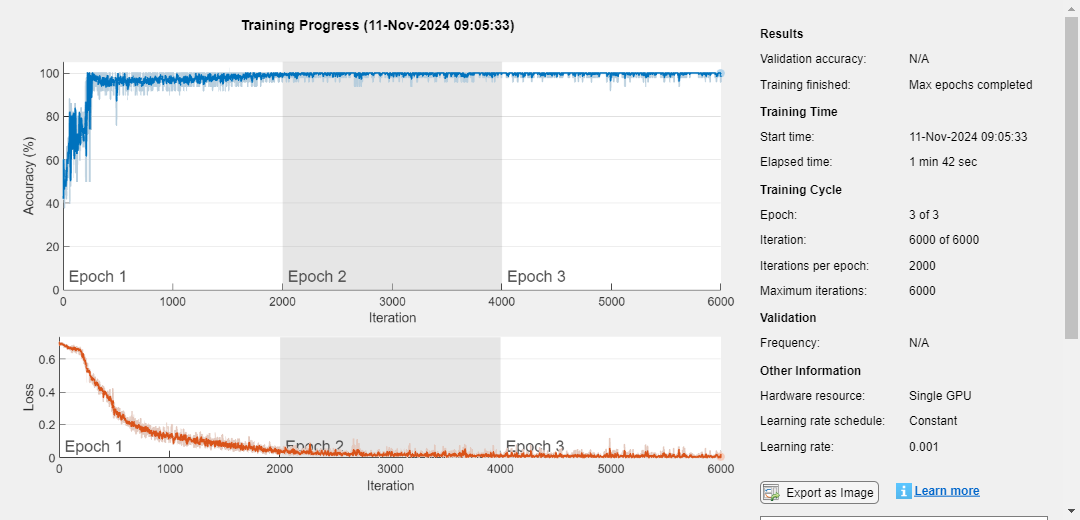

tic
for k=1:length(ITR_vector)
    disp(strcat(num2str(k/length(ITR_vector)*100),"%"))%progress indicator
    %loading the database
    str=strcat('Datasets/Dataset_ITR_',num2str(ITR_vector(k)),'_T_b_',num2str(T_b_vector(k)),'s.mat');
    load(str);
    [net_RNN, traininfo_RNN] = trainNetwork(XTrain,YTrain,layers_RNN,options);
    str=strcat('NN/net_RNN_',num2str(ITR_vector(k)),'_T_b_',num2str(T_b),'s.mat');
    save(str,"net_RNN","traininfo_RNN");
end

toc

Elapsed time is 115.352557 seconds.


### Train the feedfoward NN

Train the  feedfoward NN network with the specified training options by using `trainNetwork`.

%loading the database
tic
for k=1:length(ITR_vector)
    disp(strcat(num2str(k/length(ITR_vector)*100),"%"))%progress indicator
    str=strcat('Datasets/Dataset_ITR_',num2str(ITR_vector(k)),'_T_b_',num2str(T_b_vector(k)),'s.mat');
    load(str);
    %Training set
    A=reshape(vertcat(XTrain{:})',1,[]);%transforming XTrain to a row vector
    B=reshape(vertcat(YTrain{:})',1,[]);
    tblTrain=array2table(horzcat(double(B)'-1,A'));
    %naming the columns
    tblTrain.Properties.VariableNames(1)={'Symbol'};
    tblTrain.Properties.VariableNames(2)={'Sample'};
    % head(tblTrain);
    %Validation set
    A=reshape(vertcat(XTest{:})',1,[]);%transforming XTrain to a row vector
    B=reshape(vertcat(YTest{:})',1,[]);
    tblTest=array2table(horzcat(double(B)'-1,A'));
    %naming the columns
    tblTest.Properties.VariableNames(1)={'Symbol'};
    tblTest.Properties.VariableNames(2)={'Sample'};
    % head(tblTest);

    Mdl_ffNN = fitcnet(tblTrain,"Symbol", ...
        "Standardize",true,"ValidationData",tblTest, ...
        "Verbose",0,"LayerSizes",[38]);
    %uncomment below to check for trainning
    % iteration = Mdl_ffNN.TrainingHistory.Iteration;
    % valLosses = Mdl_ffNN.TrainingHistory.ValidationLoss;
    % [~,minIdx] = min(valLosses);
    % iteration(minIdx)
    str=strcat('NN/net_ffNN_',num2str(ITR_vector(k)),'_T_b_',num2str(T_b),'s.mat');
    save(str,"Mdl_ffNN");
end 

100%


toc

Elapsed time is 9.789957 seconds.


### Train the **Temporal Convolutional Neural Network (TCN)**

Train the TCN network with the specified training options by using `trainNetwork`.

11.1111%


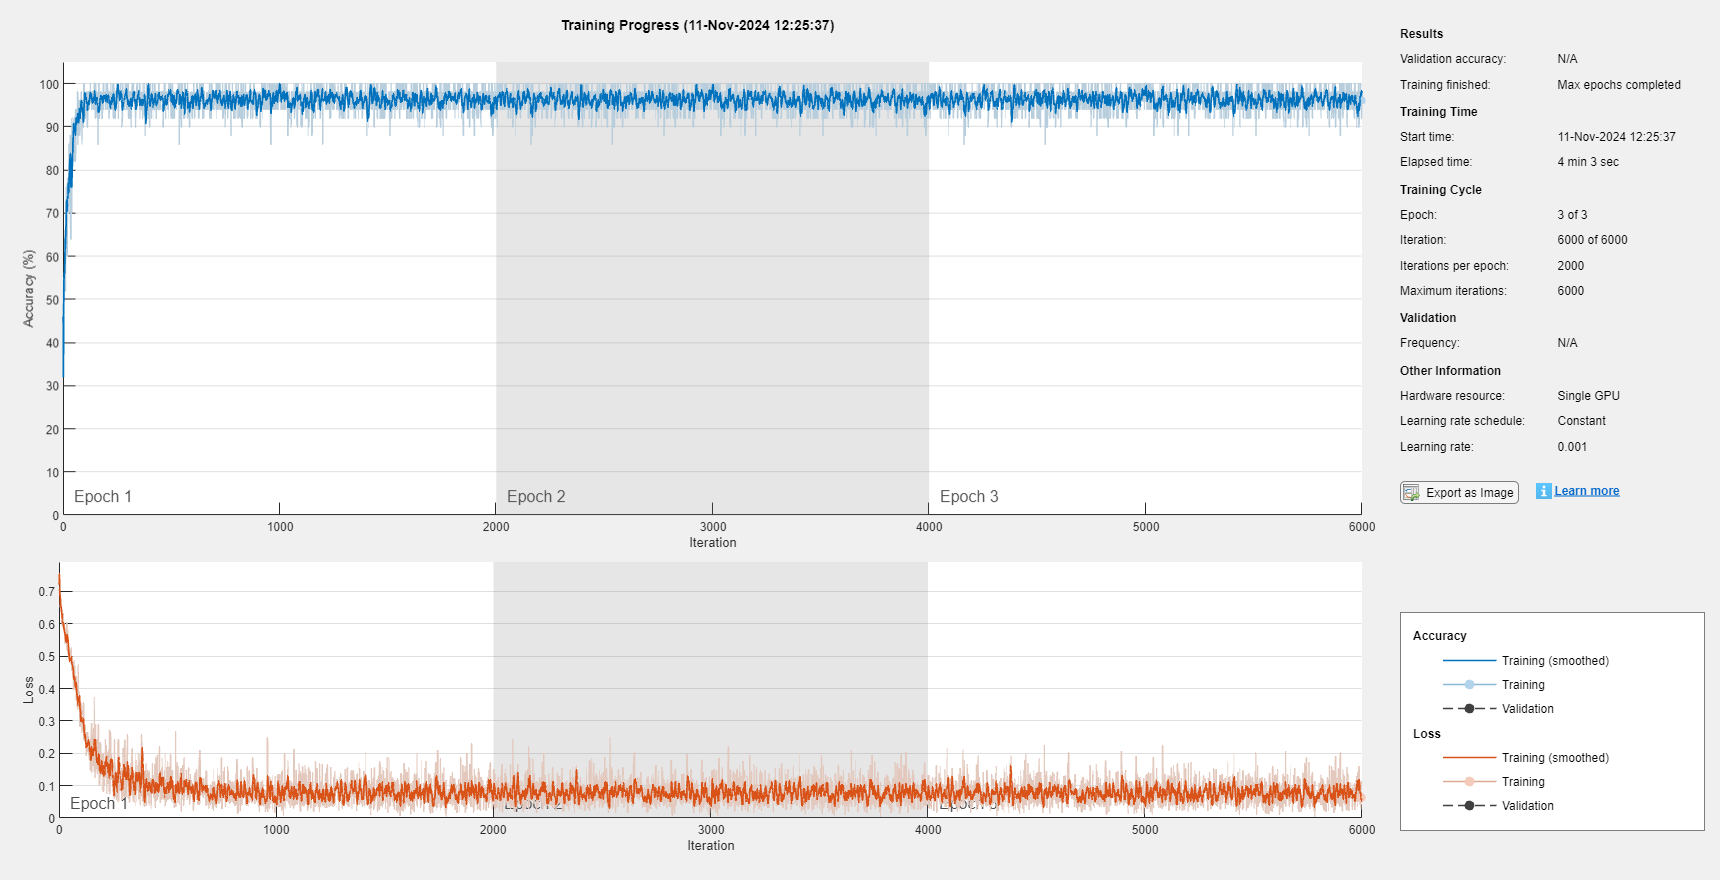

22.2222%


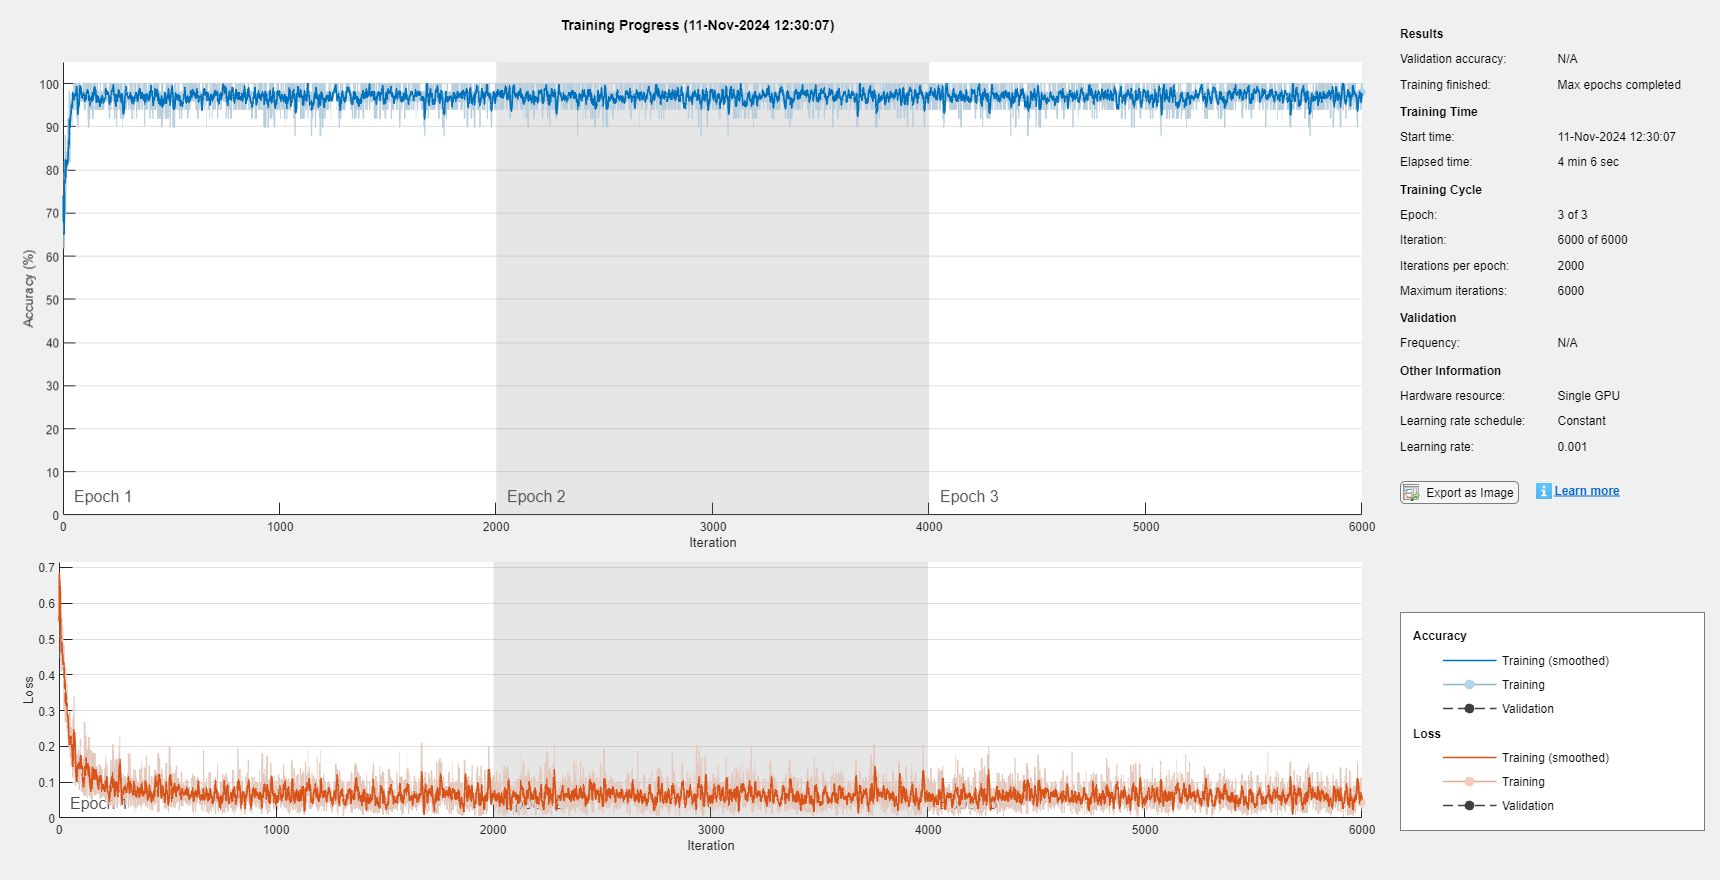

33.3333%


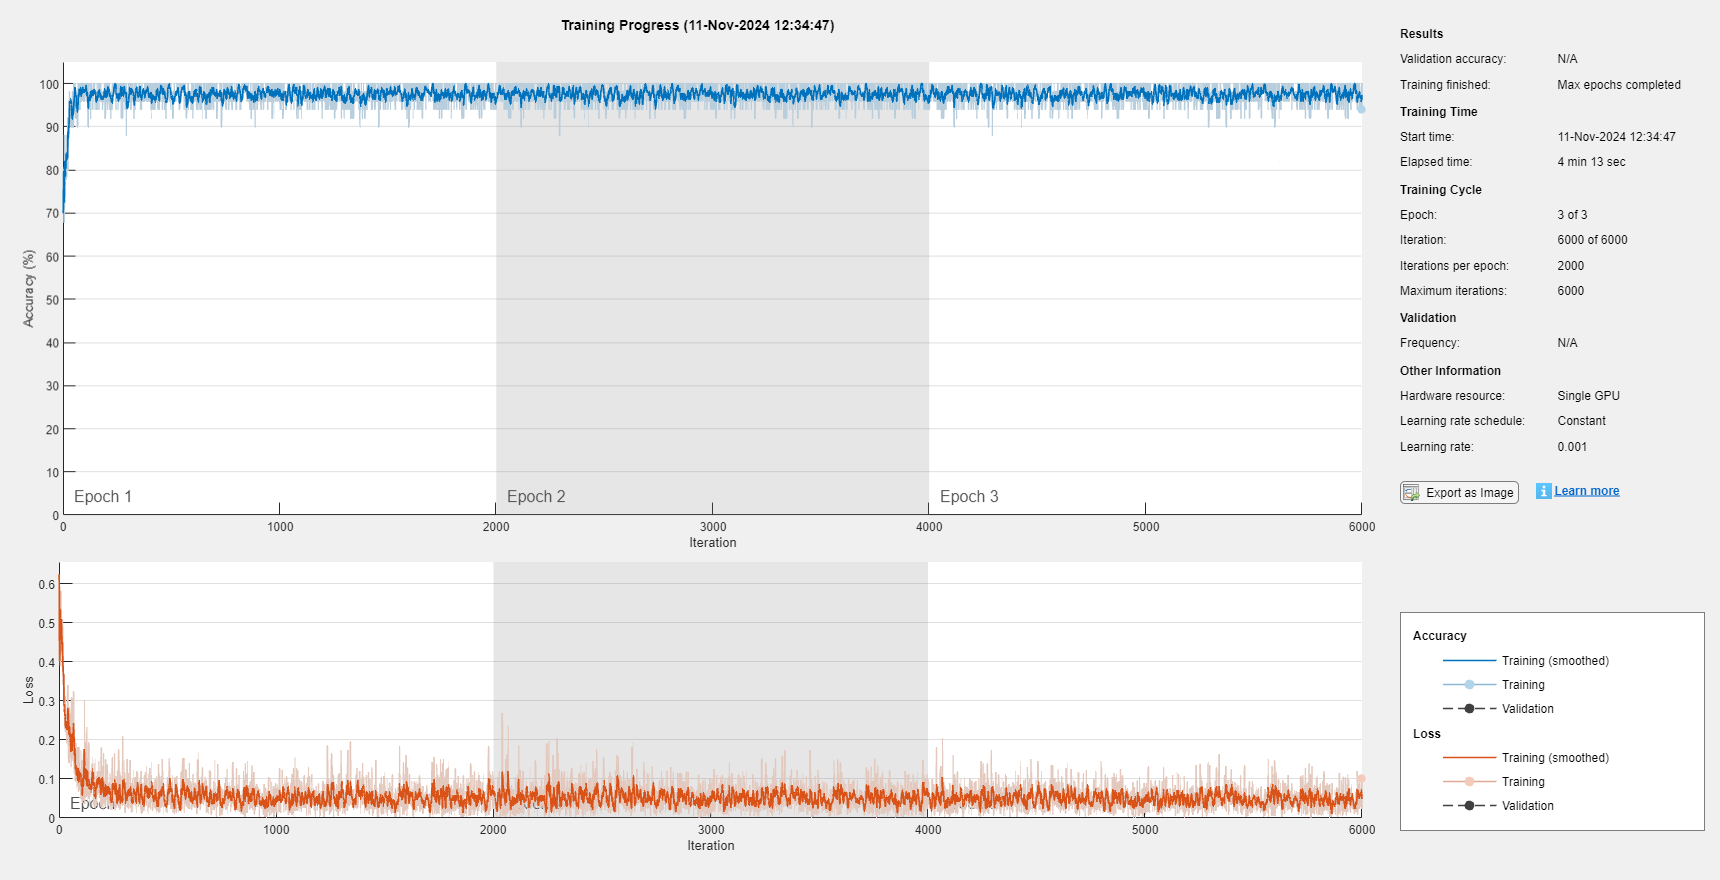

44.4444%


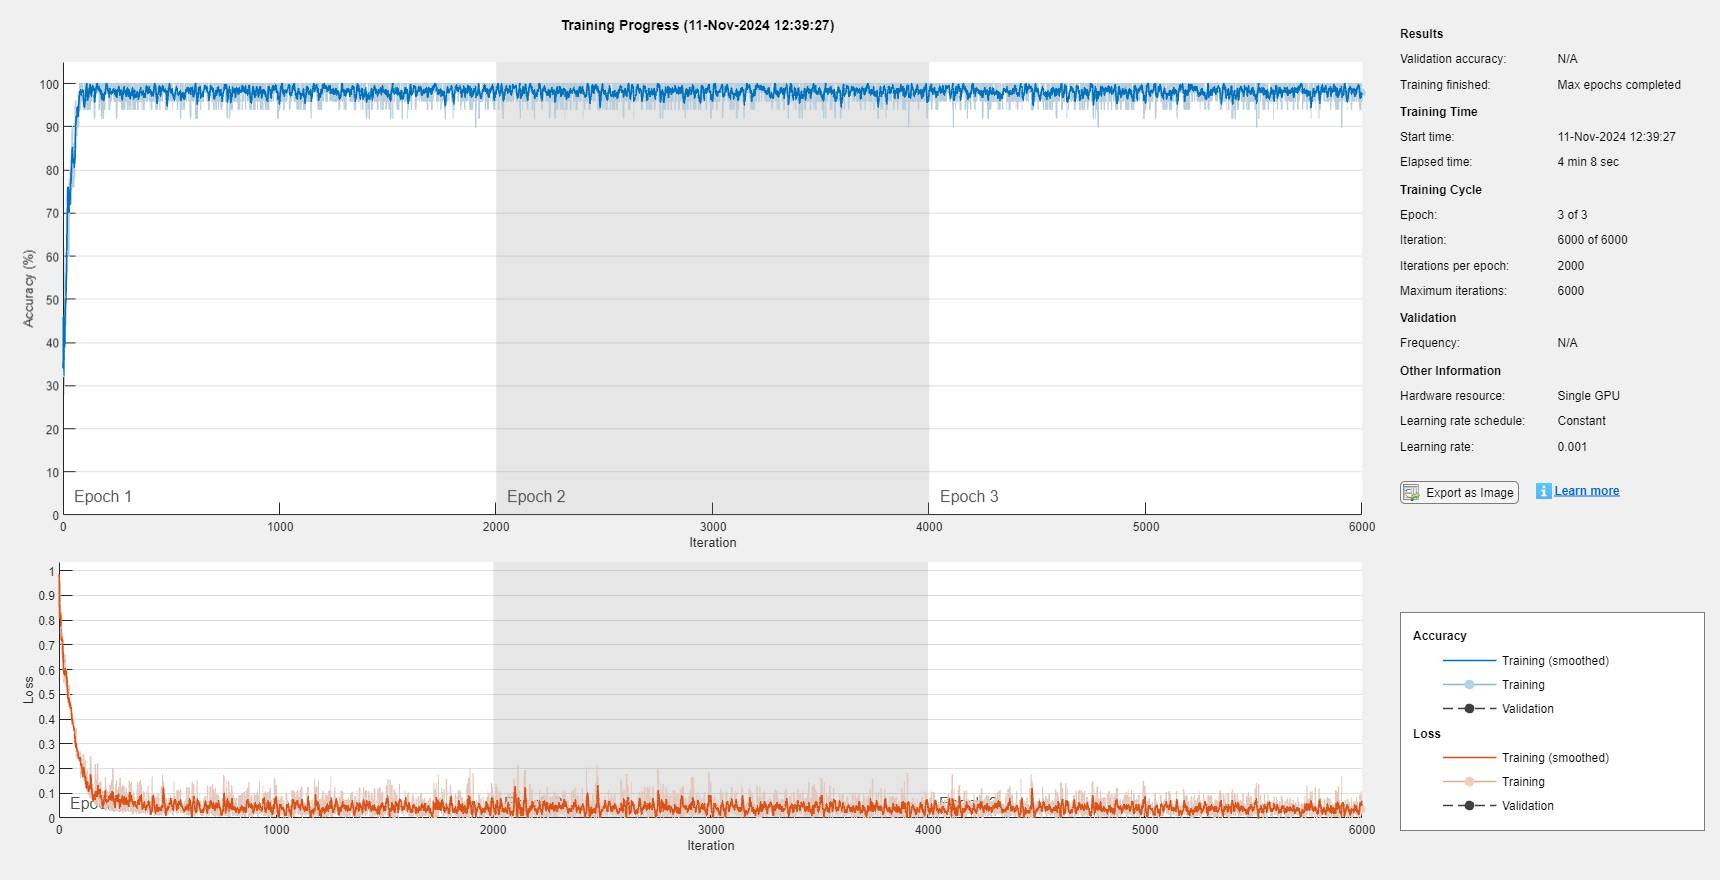

55.5556%


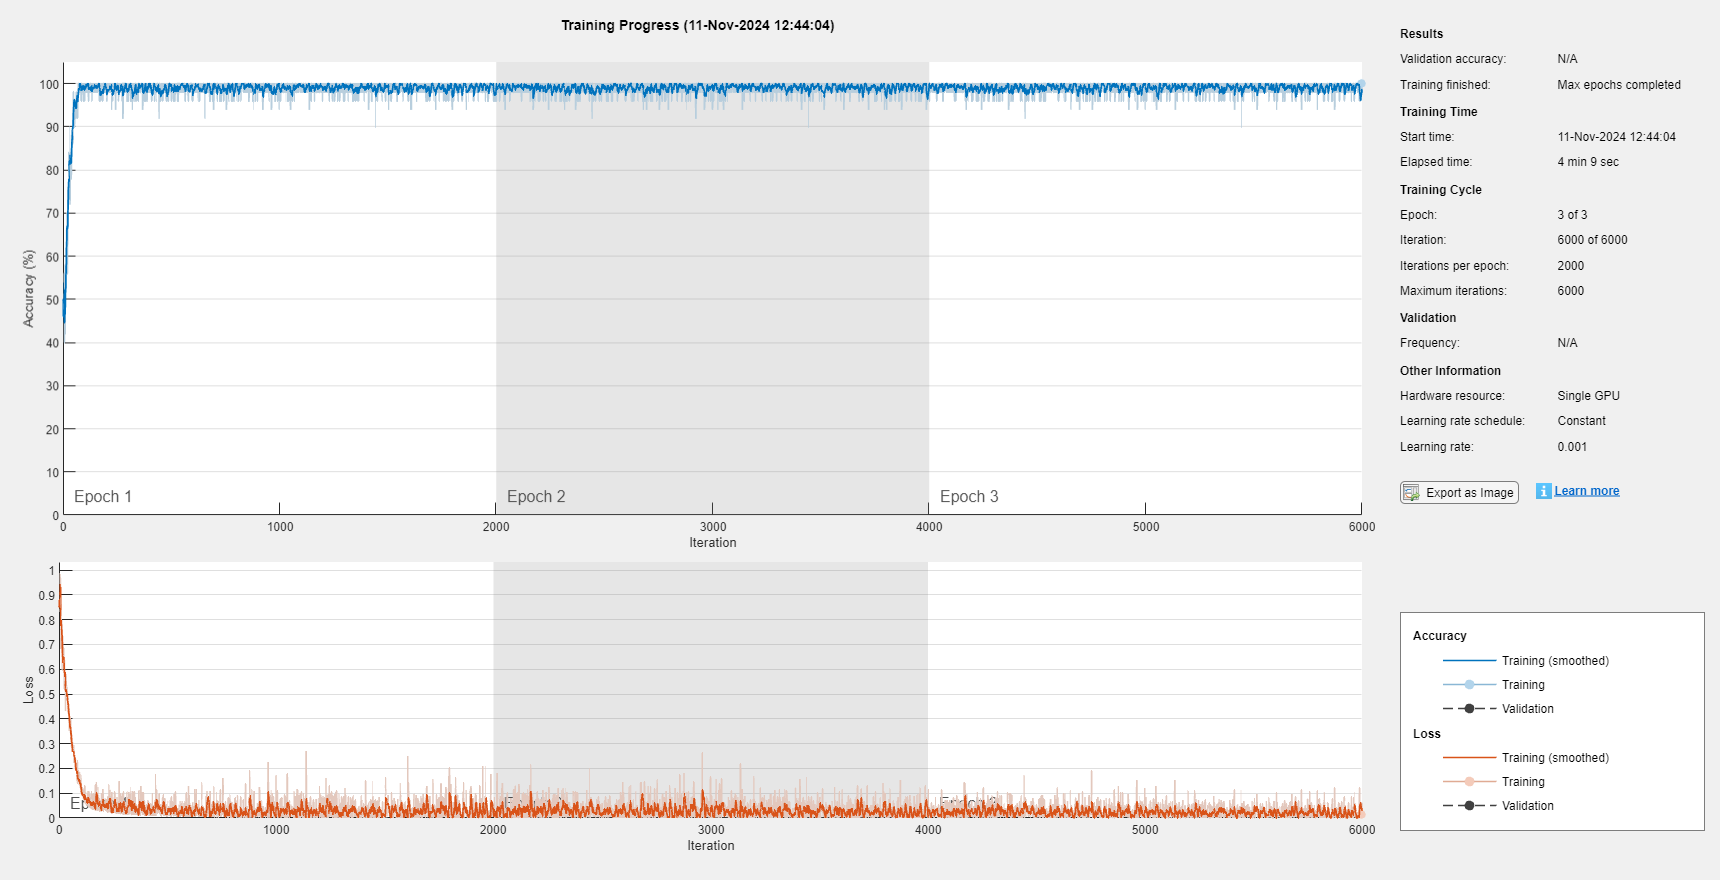

66.6667%


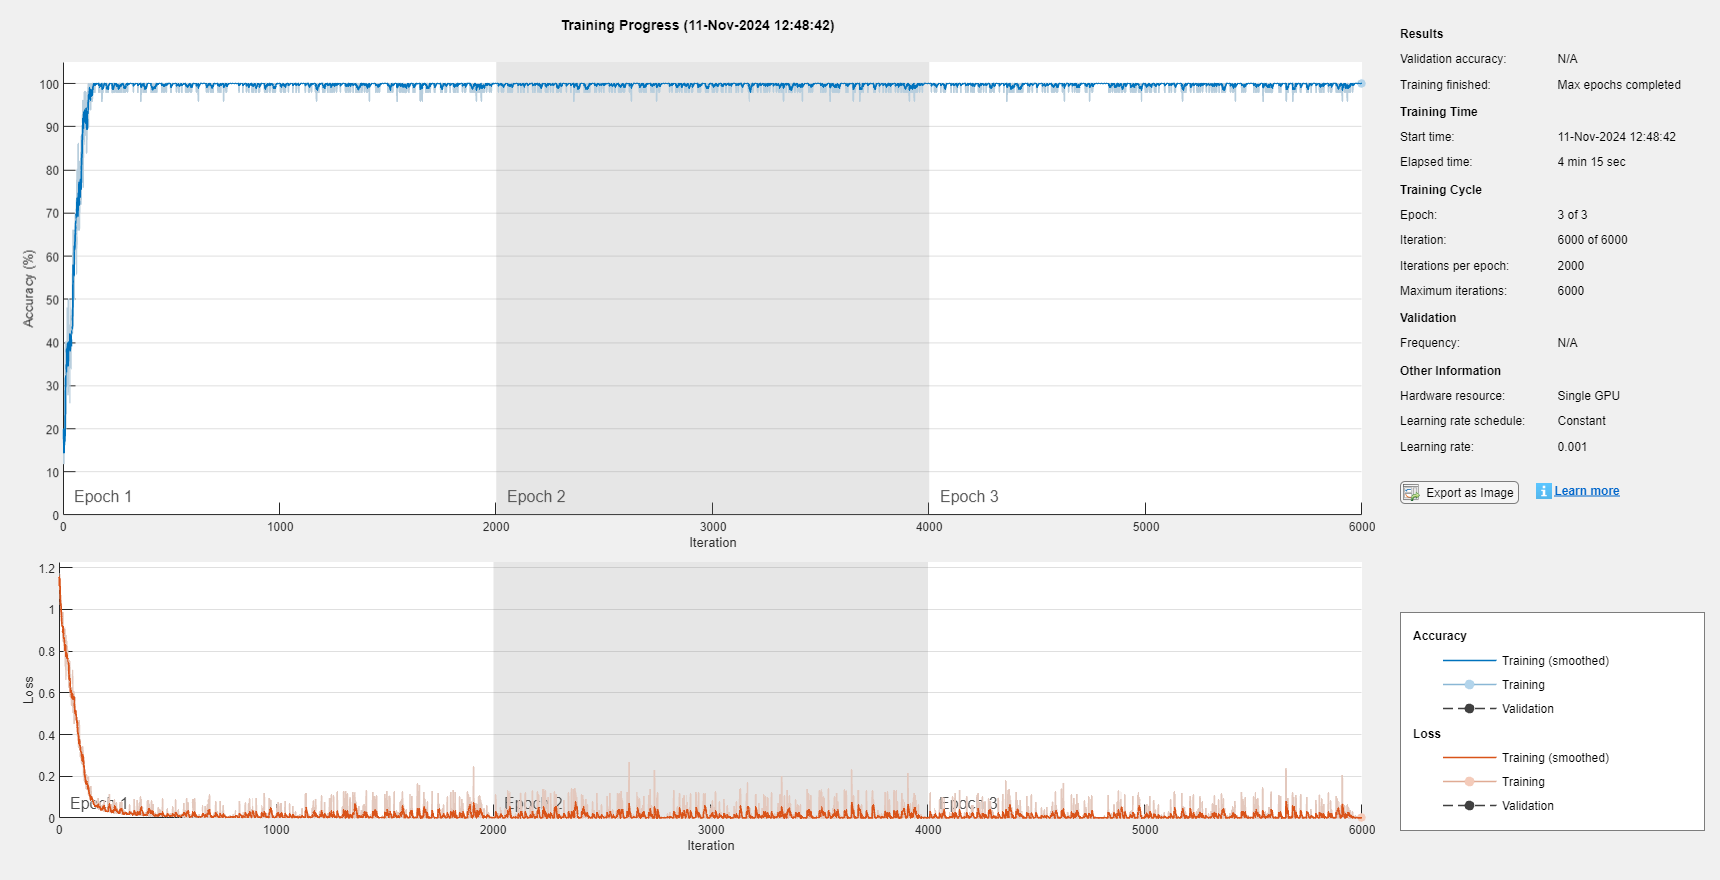

77.7778%


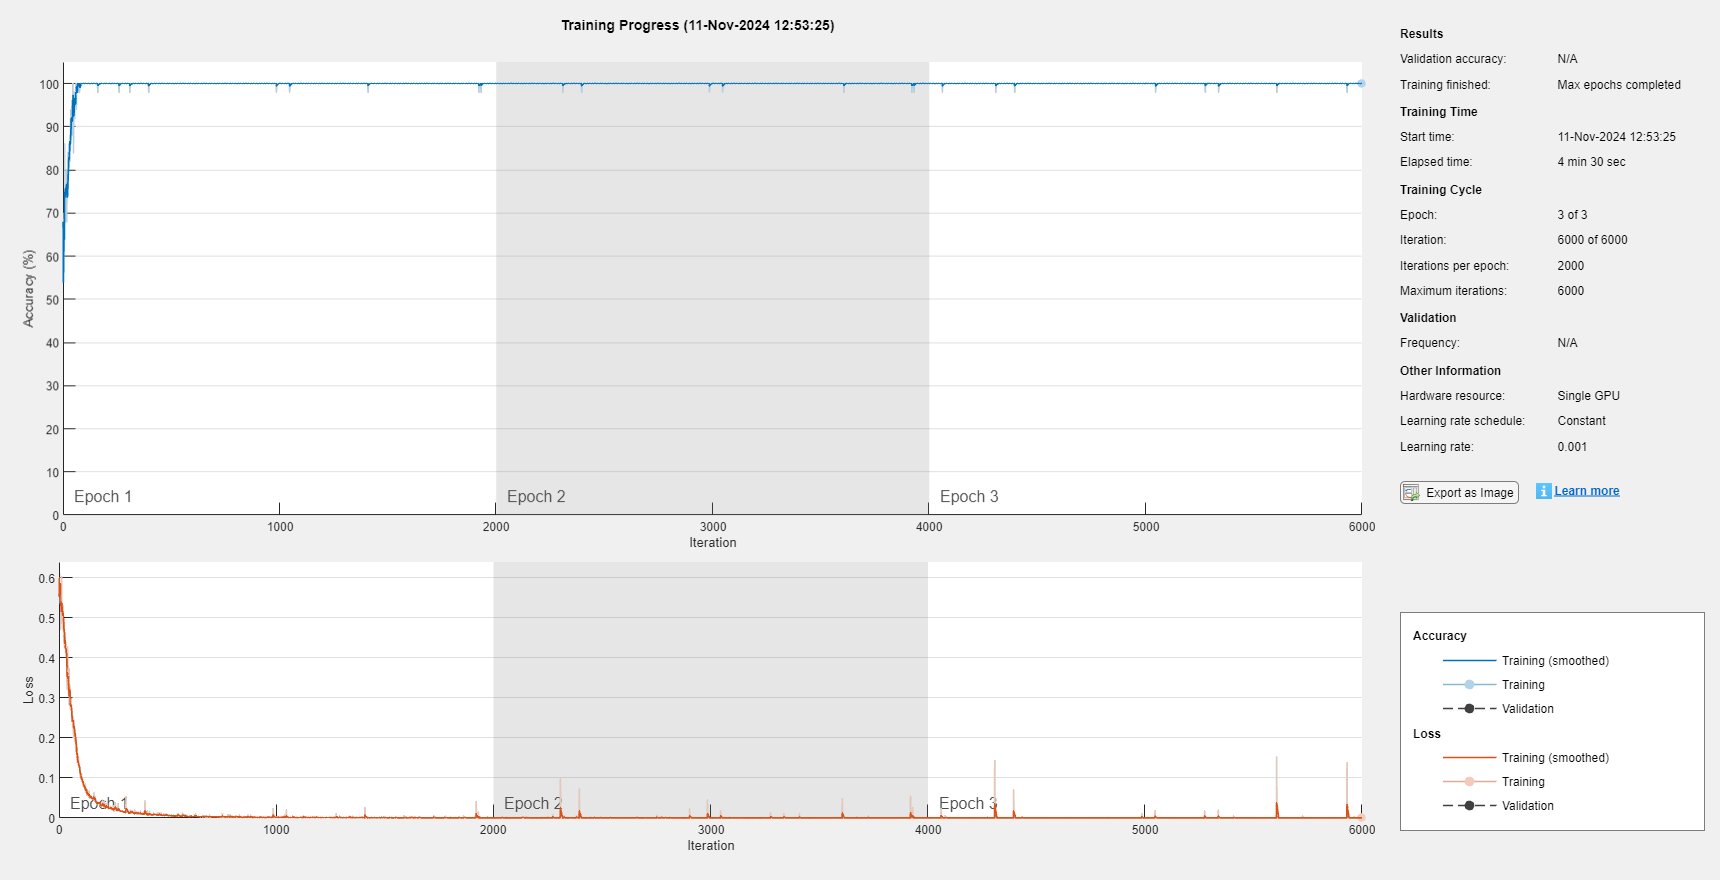

88.8889%


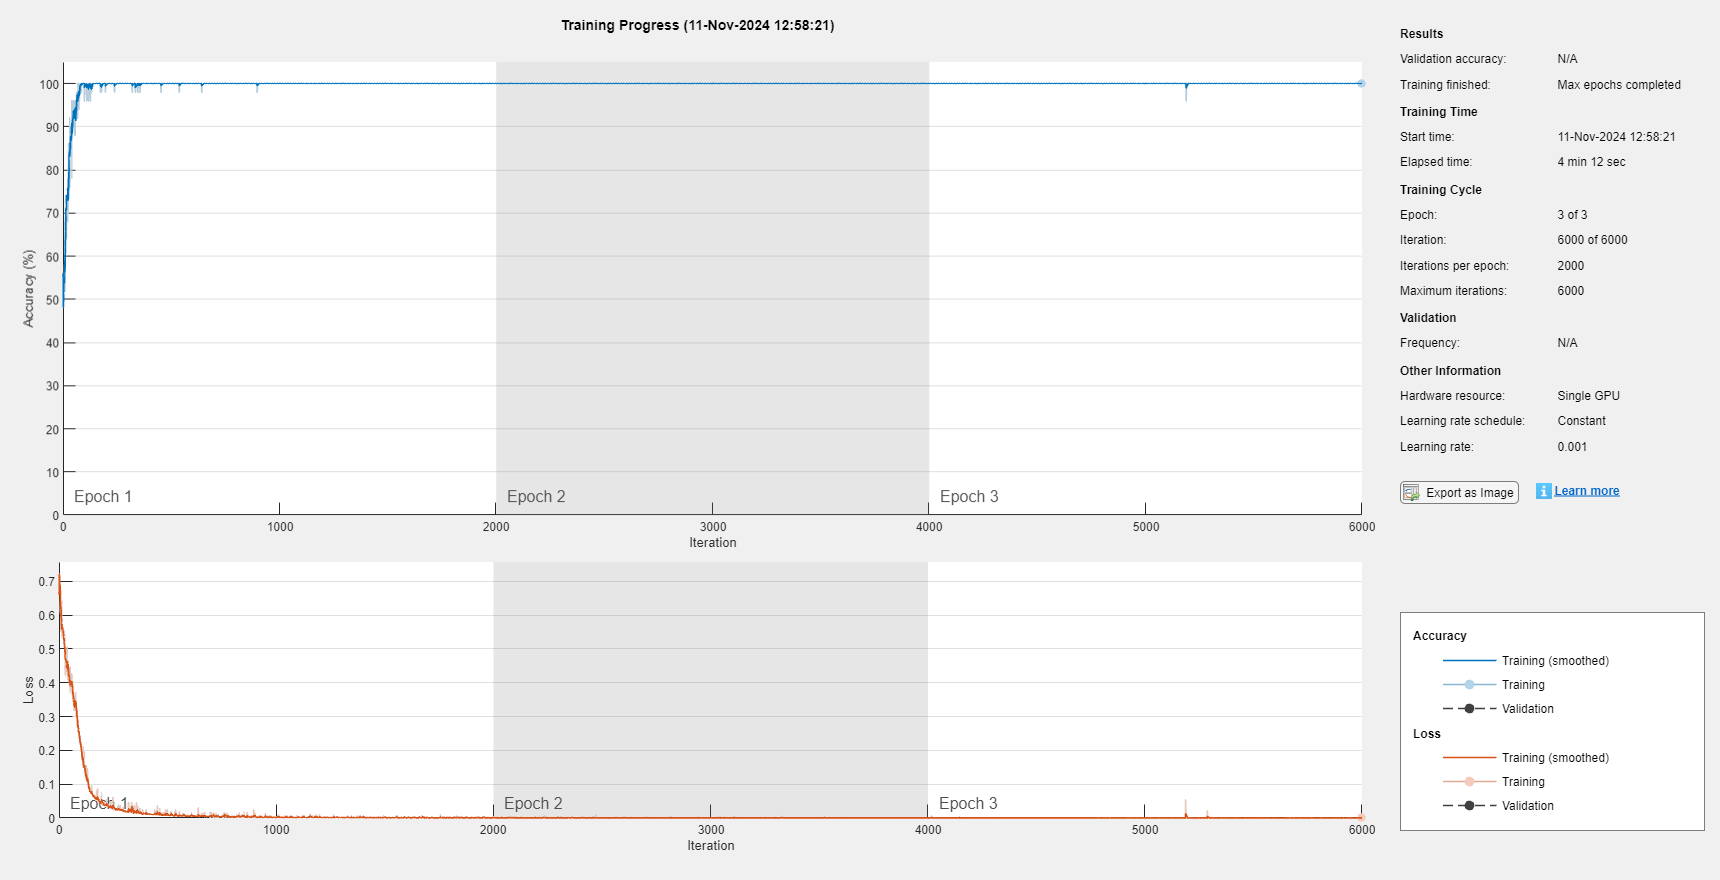

100%


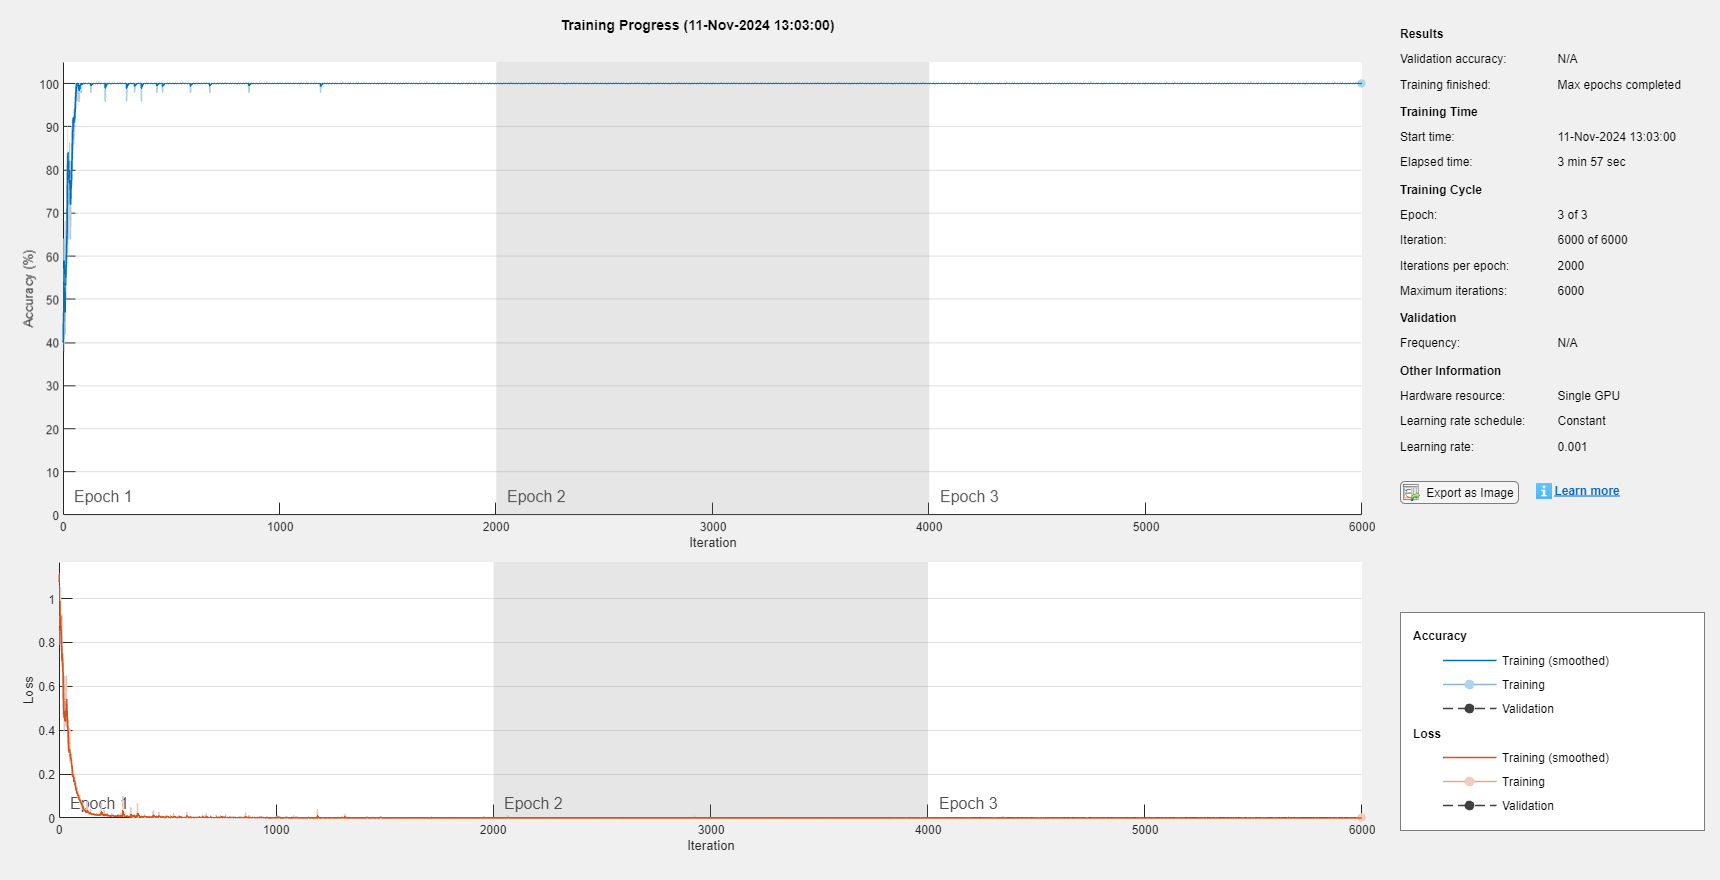

tic
for k=1:length(ITR_vector)
    disp(strcat(num2str(k/length(ITR_vector)*100),"%"))%progress indicator
    %loading the database
    str=strcat('Datasets/Dataset_ITR_',num2str(ITR_vector(k)),'_T_b_',num2str(T_b_vector(k)),'s.mat');
    load(str);
    net_TCN = trainNetwork(XTrain,YTrain,lgraph_TCN,options);
    str=strcat('NN/net_TCN_',num2str(ITR_vector(k)),'_T_b_',num2str(T_b),'s.mat');
    save(str,"net_TCN");
end

toc

Elapsed time is 2507.057552 seconds.


### Testing the models

BER_net_BiRNN=zeros(1,length(ITR_vector));
BER_net_RNN=zeros(1,length(ITR_vector));
BER_net_TCN=zeros(1,length(ITR_vector));
BER_net_ffNN=zeros(1,length(ITR_vector));
tic
for k=1:length(T_b_vector)
    %loading the Database
    str=strcat('Datasets/Dataset_ITR_',num2str(ITR_vector(k)),'_T_b_',num2str(T_b_vector(k)),'s.mat');
    load(str);
    %loading the BiRNN model
    str=strcat('NN/net_BiRNN_',num2str(ITR_vector(k)),'_T_b_',num2str(T_b),'s.mat');
    load(str);
    %loading the RNN model
    str=strcat('NN/net_RNN_',num2str(ITR_vector(k)),'_T_b_',num2str(T_b),'s.mat');
    load(str);
    %loading the TCN model
    str=strcat('NN/net_TCN_',num2str(ITR_vector(k)),'_T_b_',num2str(T_b),'s.mat');
    load(str);
    %loading the feedforward NN model
    str=strcat('NN/net_ffNN_',num2str(ITR_vector(k)),'_T_b_',num2str(T_b),'s.mat');
    load(str);
    
    %Decoding BiRNN
    YPred_BiRNN = classify(net_BiRNN, XTest, 'MiniBatchSize', 1);  % MiniBatchSize can be adjusted
    %Decoding RNN
    YPred_RNN = classify(net_RNN, XTest, 'MiniBatchSize', 1);  % MiniBatchSize can be adjusted
    %Decoding TCN
    YPred_TCN = classify(net_TCN,XTest);
    
    %Measuring performance
    % BiRNN accuracy by comparing YPred and YTest
    correctPredictions_BiRNN = cellfun(@(y_pred, y_true) mean(y_pred == y_true), YPred_BiRNN, YTest);
    BER_net_BiRNN(k) =1- mean(correctPredictions_BiRNN);
    str=strcat('net_BiRNN, ITR=',num2str(ITR_vector(k)),' T_b=',num2str(T_b),' BER=', num2str(BER_net_BiRNN(k)));
    disp(str);
    % RNN accuracy by comparing YPred and YTest
    correctPredictions_RNN = cellfun(@(y_pred, y_true) mean(y_pred == y_true), YPred_RNN, YTest);
    BER_net_RNN(k) =1- mean(correctPredictions_RNN);
    str=strcat('net_RNN, ITR=',num2str(ITR_vector(k)),' T_b=',num2str(T_b),' BER=', num2str(BER_net_RNN(k)));
    disp(str);
    % TCN accuracy by comparing YPred and YTest
    correctPredictions_TCN = cellfun(@(y_pred, y_true) mean(y_pred == y_true), YPred_TCN, YTest);
    BER_net_TCN(k) =1- mean(correctPredictions_TCN);
    str=strcat('net_TCN, ITR=',num2str(ITR_vector(k)),' T_b=',num2str(T_b),' BER=', num2str(BER_net_TCN(k)));
    disp(str);
    % Feedforward NN accuracy by comparing YPred and YTest
    %Validation set
    A=reshape(vertcat(XTest{:})',1,[]);%transforming XTrain to a row vector
    B=reshape(vertcat(YTest{:})',1,[]);
    tblTest=array2table(horzcat(double(B)'-1,A'));
    %naming the columns
    tblTest.Properties.VariableNames(1)={'Symbol'};
    tblTest.Properties.VariableNames(2)={'Sample'};
    % head(tblTest);
    BER_net_ffNN(k) = loss(Mdl_ffNN,tblTest,"Symbol");  

    str=strcat('net_ffNN, ITR=',num2str(ITR_vector(k)),' T_b=',num2str(T_b),' BER=', num2str(BER_net_ffNN(k)));
    disp(str);

end
toc

net_BiRNN, ITR=20 T_b=1.9 BER=0.05641


net_RNN, ITR=20 T_b=1.9 BER=0.03822


net_TCN, ITR=20 T_b=1.9 BER=0.0357


net_ffNN, ITR=20 T_b=1.9 BER=0.18049


net_BiRNN, ITR=25 T_b=2.3 BER=0.03124


net_RNN, ITR=25 T_b=2.3 BER=0.03539


net_TCN, ITR=25 T_b=2.3 BER=0.03077


net_ffNN, ITR=25 T_b=2.3 BER=0.14886


net_BiRNN, ITR=30 T_b=2.6 BER=0.02431


net_RNN, ITR=30 T_b=2.6 BER=0.02562


net_TCN, ITR=30 T_b=2.6 BER=0.02369


net_ffNN, ITR=30 T_b=2.6 BER=0.12286


net_BiRNN, ITR=35 T_b=3 BER=0.03467


net_RNN, ITR=35 T_b=3 BER=0.0304


net_TCN, ITR=35 T_b=3 BER=0.01872


net_ffNN, ITR=35 T_b=3 BER=0.091924


net_BiRNN, ITR=40 T_b=3.5 BER=0.01431


net_RNN, ITR=40 T_b=3.5 BER=0.00964


net_TCN, ITR=40 T_b=3.5 BER=0.00985


net_ffNN, ITR=40 T_b=3.5 BER=0.047119


net_BiRNN, ITR=45 T_b=3.9 BER=0.00335


net_RNN, ITR=45 T_b=3.9 BER=0.00573


net_TCN, ITR=45 T_b=3.9 BER=0.00244


net_ffNN, ITR=45 T_b=3.9 BER=0.01109


net_BiRNN, ITR=50 T_b=4.4 BER=7e-05


net_RNN, ITR=50 T_b=4.4 BER=0.0003


net_TCN, ITR=50 T_b=4.4 BER=0.00017


net_ffNN, ITR=50 T_b=4.4 BER=0.00016001


net_BiRNN, ITR=55 T_b=5 BER=8e-05


net_RNN, ITR=55 T_b=5 BER=4e-05


net_TCN, ITR=55 T_b=5 BER=0


net_ffNN, ITR=55 T_b=5 BER=1.0031e-05


net_BiRNN, ITR=60 T_b=5.7 BER=0


net_RNN, ITR=60 T_b=5.7 BER=0


net_TCN, ITR=60 T_b=5.7 BER=0


net_ffNN, ITR=60 T_b=5.7 BER=0


save("NN/BER_NN.mat","BER_net_BiRNN","BER_net_RNN","BER_net_ffNN","BER_net_TCN","T_b_vector","ITR_vector");

Elapsed time is 1253.357603 seconds.


### Plotting

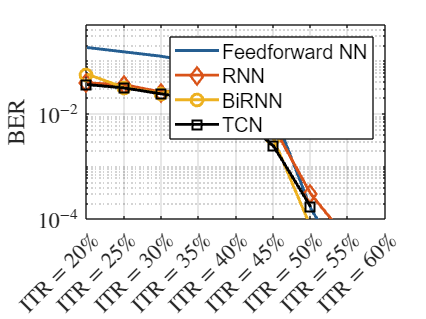

load NN/BER_NN.mat

figure;% open a new plot canvas
color = {'#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#4DBEEE','#A2142F'}; %list of colors from https://www.mathworks.com/help/matlab/creating_plots/specify-plot-colors.html
line_width=linspace(1,3,length(color));%specify the width for each line in the plot
marker={'-','-+','-d','-.','-x','-o','-s','-*','-|','-^'};% marker symbols are given at https://www.mathworks.com/help/matlab/creating_plots/create-line-plot-with-markers.html

%feedforward NN
semilogy(ITR_vector,BER_net_ffNN,'Color','#255E91','LineWidth',2); grid on;hold on
%BiRNN
semilogy(ITR_vector,BER_net_RNN,marker{3},'Color','#D95319','LineWidth',2,'MarkerSize',8);
%RNN
semilogy(ITR_vector,BER_net_BiRNN,marker{6},'Color','#EDB120','LineWidth',2,'MarkerSize',8);
%TCN
semilogy(ITR_vector,BER_net_TCN,marker{7},'Color','black','LineWidth',2,'MarkerSize',8);
%xlabel
set(gca, 'XTick', ITR_vector);
x_ticks=cell(1,length(ITR_vector));
for m=1:length(ITR_vector)
  x_ticks{m}=strcat("$\mathrm{ITR}=",num2str(ITR_vector(m)),"\%$");
end
set(gca, 'XTickLabel', x_ticks, 'TickLabelInterpreter', 'latex');
%ylabel
ylabel('BER','Interpreter','latex');
legend('Feedforward NN','RNN','BiRNN','TCN');
set(gca,'FontSize',fontsize);
axis([ITR_vector(1) ITR_vector(end) 1e-4 0.5]);

### References

[1] P. Hofmann, J. Torres Gómez, F. Dressler, and F. H. P. Fitzek, “Testbed-based Receiver Optimization for SISO Molecular Communication Channels,” in 5th IEEE International Balkan Conference Communications and Networking (BalkanCom 2022), Sarajevo, Bosnia and Herzegovina: IEEE, Aug. 2022, pp. 120–125.

[2] Pit Hofmann, Jorge Torres Gómez, Frank H. P. Frank H.P. , Falko Dressler, April 27, 2023, "Dataset for Macroscale Molecular Communication Testbed", IEEE Dataport, doi: [https://dx.doi.org/10.21227/ytkm-xp81.](https://dx.doi.org/10.21227/ytkm-xp81.)